## Serie de tiempo

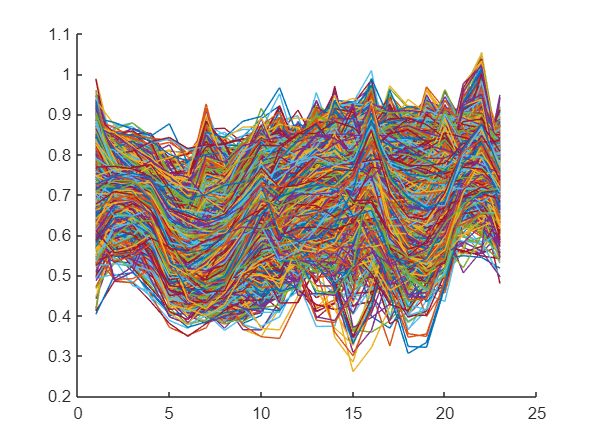

% indxs=find(info_hdf.anio>=2003 & info_hdf.anio<=2022);

% indxs=find(info_hdf.anio==2022);
% datos=arr_ndvi_sgf(:,:,indxs);

% Esta variable se utiliza solo para tepezintla
datos=arr_ndvi_sgf;

[alto,ancho,~]=size(datos);
figure; 
hold on
temp_Mediana=[];
temp_Mean=[];
temp_Mode=[];
temp_Range=[];
temp_Desv=[];
temp_Min=[];
temp_Max=[];
temp_Std=[];
temp_Mad=[];
temp_valor=[];
id=1;
for i=1:alto
     for j=1:ancho
        if(study_area(i,j)==1)
            serie = reshape(datos(i,j,:),[],1);
            plot(serie)
            temp_Mediana(id) =median(serie);
            temp_Mean(id)=mean(serie);
            temp_Mode(id)=mode(serie);
            temp_Range(id)=range(serie);
            temp_Desv(id)=std(serie);
            temp_Min(id)=min(serie);
            temp_Max(id)=max(serie);
            temp_Mad(id)=mad(serie);
            temp_valor(id)=0;
            id=id+1;
        end
    end
end
hold off


tab_data=table( temp_Mediana',temp_Mean',temp_Mode',temp_Range',temp_Desv',temp_Min',temp_Max',temp_Mad',temp_valor',VariableNames=["Mediana","Promedio","Moda","Rango","Desviacion","Minimos","Maximos","Mad","Valor"]);

Salvar los datos

writetable(tab_data,'M.xls')


Leer los datos almacenados

dir_data_procces="C:\Users\SALAS\Desktop\DATA_NARANJAS\PROCESS\";
file_read=["01_Cultivo_1.xls","01_Cultivo_3.xls","02_Bosque.xls","02_CIUDAD.xls","02_Selva.xls"];
t_positiv_1=readtable(dir_data_procces+file_read(1));
t_positiv_2=readtable(dir_data_procces+file_read(2));
t_negativ_1=readtable(dir_data_procces+file_read(3));
t_negativ_2=readtable(dir_data_procces+file_read(4));
t_negativ_3=readtable(dir_data_procces+file_read(5));

Union de valores

data_positiv=t_positiv_2;

data_negativ=[t_negativ_1;t_negativ_2;t_negativ_3];

[a,b]=size(data_positiv);
[c,d]=size(data_negativ);

data_learn=[data_positiv(1:(a/2), :); data_negativ(1:(c/2),:)];
x=int16(a/2);
y=int16(c/2);
data_test=[data_positiv(x:a,:);data_negativ(y:c,:)];

data_all=[data_test;data_learn];


data_tepezintla=tab_data;